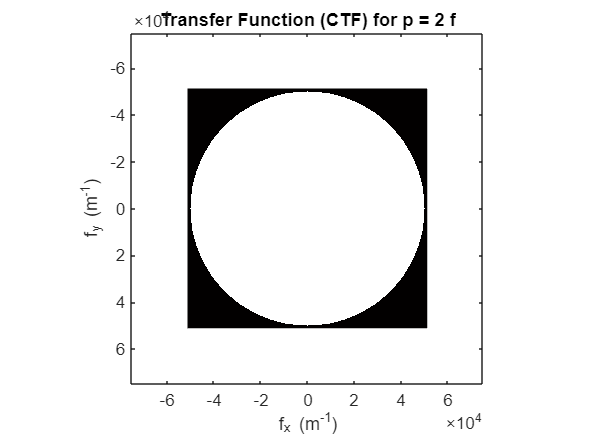

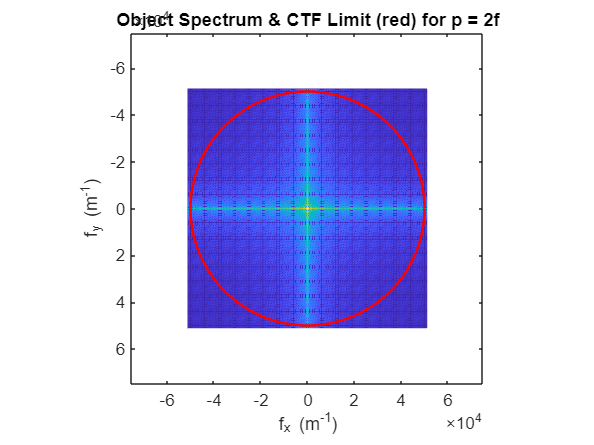

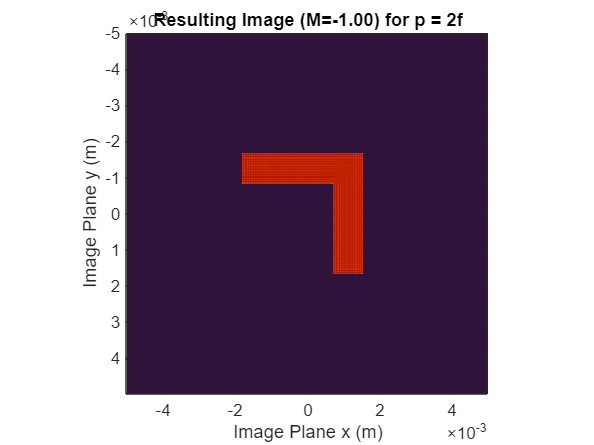

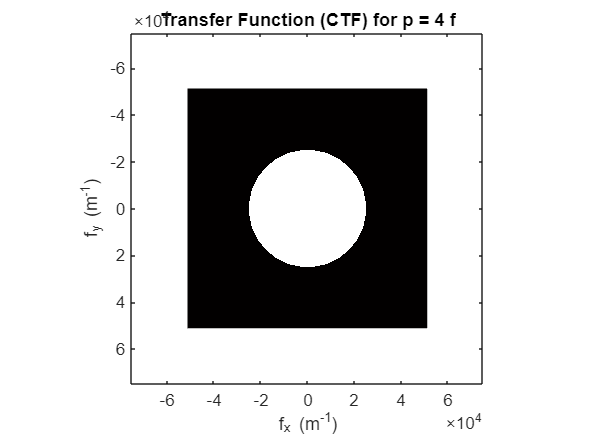

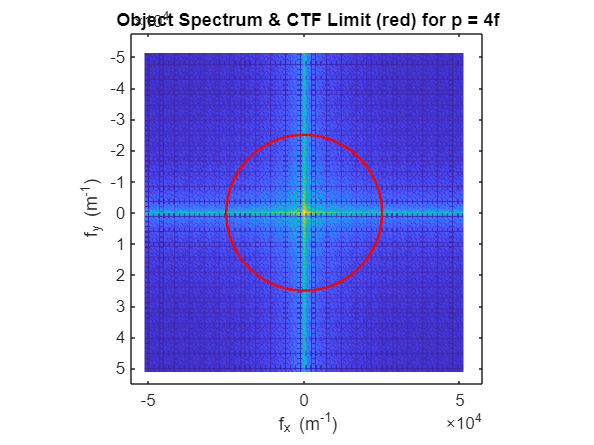

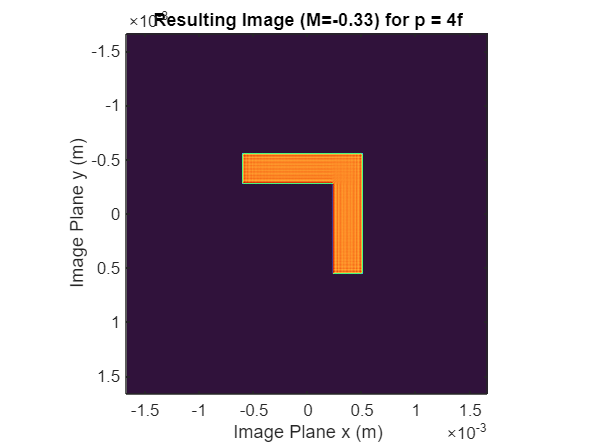

% OPTI 512L
% LAB 5
% Mohanbabu Mani

% 1.

N = 1024;               
L = 10e-3;              
dx = L / N;             
lambda = 500e-9;       
f = 50e-3;             
D = 5e-3;              
x = (-N/2 : N/2-1) * dx;
[X, Y] = meshgrid(x, x);
df = 1 / L;
fx = (-N/2 : N/2-1) * df;
[Fx, Fy] = meshgrid(fx, fx);
F_rho = sqrt(Fx.^2 + Fy.^2); 
object = zeros(N, N);
L_height = round(N/3);
L_width = round(N/3);
L_thick = round(N/12);
v_bar_x_indices = round(N/2 - L_width/3 - L_thick/2) : round(N/2 - L_width/3 + L_thick/2);
v_bar_y_indices = round(N/2 - L_height/2) : round(N/2 + L_height/2);
h_bar_y_indices = round(N/2 + L_height/2 - L_thick) : round(N/2 + L_height/2);
h_bar_x_indices = v_bar_x_indices(1) : (v_bar_x_indices(1) + L_width);
object(v_bar_y_indices, v_bar_x_indices) = 1;
object(h_bar_y_indices, h_bar_x_indices) = 1;
G_obj = fftshift(fft2(object));
p_values = [2*f, 4*f];
max_rho_c = D / (2 * lambda * min(p_values));

for i = 1:length(p_values)
    p = p_values(i);
    q = 1 / (1/f - 1/p);
    M = -q/p;
    rho_c = D / (2 * lambda * p);
    CTF = zeros(N, N);
    CTF(F_rho <= rho_c) = 1;
    G_img = G_obj .* CTF;
    img_field = ifft2(ifftshift(G_img));
    img_intensity = abs(img_field).^2;
    img_intensity = img_intensity / max(img_intensity(:));
    
    figure('Name', sprintf('CTF for p=%.0ff', p/f), 'NumberTitle', 'off');
    imagesc(fx(1,:), fx(1,:), CTF);
    axis image;
    colormap(gca, 'hot');
    title(sprintf('Transfer Function (CTF) for p = %.0f f', p/f));
    xlabel('f_x (m^{-1})');
    ylabel('f_y (m^{-1})');
    xlim([-1.5*max_rho_c, 1.5*max_rho_c]);
    ylim([-1.5*max_rho_c, 1.5*max_rho_c]);
    
    figure('Name', sprintf('Spectrum & CTF for p=%.0ff', p/f), 'NumberTitle', 'off');
    imagesc(fx(1,:), fx(1,:), log(1 + abs(G_obj)));
    hold on;

    theta = 0:0.01:2*pi;
    plot(rho_c*cos(theta), rho_c*sin(theta), 'r-', 'LineWidth', 1.5);
    hold off;
    axis image;
    colormap(gca, 'parula');
    title(sprintf('Object Spectrum & CTF Limit (red) for p = %.0ff', p/f));
    xlabel('f_x (m^{-1})');
    ylabel('f_y (m^{-1})');
    xlim([-1.5*max_rho_c, 1.5*max_rho_c]);
    ylim([-1.5*max_rho_c, 1.5*max_rho_c]);

    figure('Name', sprintf('Resulting Image for p=%.0ff', p/f), 'NumberTitle', 'off');
    img_coords = x * abs(M);
    imagesc(img_coords, img_coords, flipud(fliplr(img_intensity)));
    axis image;
    colormap(gca, 'turbo');
    title(sprintf('Resulting Image (M=%.2f) for p = %.0ff', M, p/f));
    xlabel('Image Plane x (m)');
    ylabel('Image Plane y (m)');
end

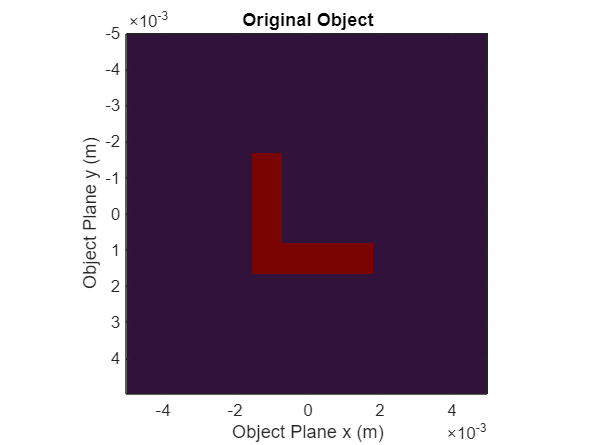


figure('Name', 'Original Object', 'NumberTitle', 'off');
imagesc(x, x, object);
axis image;
colormap('turbo');
title('Original Object');
xlabel('Object Plane x (m)');
ylabel('Object Plane y (m)');